# Airfoil: Eppler 197

clear all; close all; clc;

## Flight Conditions Import

Re = 379824;
v = 24; %m/s
gamma = 1.4;
T = 286;
R = 286;

### Design Decisions

sweep_qc = 0; %quarter-chord sweep angle
sweep_max = 0;
d = 0.1; %fuselage diameter [m]
WL = 92.1058; %wing loading
Wg = 22.2297; %gross weight
AR = 4.5; %aspect ratio

## 2D Airfoil Data Import

Cl_alpha = 0.1182;
alpha0 = -2.669; %deg
Cl_min = -0.686;
Cl_max = 1.2295;
Cd_min = 0.0085;
TR = 0.1349;

## Wing Sizing

S = Wg/WL %reference wing area

S = 0.2413

b = sqrt(AR*S) %wing span

b = 1.0421

c = b/AR %chord length

c = 0.2316

## 3D Lift Analysis

####     Mach Number

a = sqrt(gamma*R*T); %local speed of sound
M = v/a

M = 0.0709

####     3D Lift Curve Parameters

CL_max = 0.9*Cl_max*cosd(sweep_qc)

CL_max = 1.1066

beta = sqrt(1 - M^2)

beta = 0.9975

eta = (Cl_alpha*180/pi) / (2*pi/beta)

eta = 1.0751

F = 1.07*(1+d/b)^2

F = 1.2852

Assuming that the reference area is equal to the exposed area, then the wetted area can be estimated. 

S_exp = S;
S_wet = S_exp*(1.977+0.52*TR)

S_wet = 0.4941

Calculating the 3D lift curve slope:

CL_alpha = ((2*pi*AR)/(2+sqrt(4+((AR^2*beta^2)/(eta^2))*(1+((tand(sweep_max)^2)/(beta^2))))))*(S_exp/S)*F;
CL_alpha = CL_alpha*pi/180

CL_alpha = 0.0957

####     Plotting 3D Lift Curve

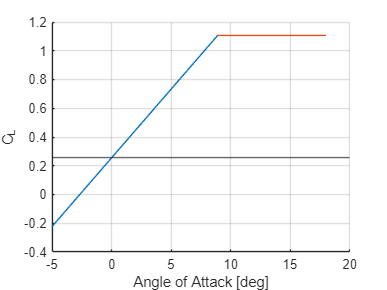

alpha_stall = (CL_max/CL_alpha) + alpha0;
alpha = linspace(-5,alpha_stall,100);
alpha_ps = linspace(alpha_stall,18,100);
CL_PS = CL_max*ones(1,length(alpha_ps));
CL = CL_alpha*(alpha - alpha0);

figure()
hold on
plot(alpha,CL)
plot(alpha_ps,CL_PS)
yline(0.26)
grid on
xlabel('Angle of Attack [deg]')
ylabel('C_L')

## Drag Analysis

#### Open Airfoil Data from XFLR5

data = readtable('T1_Re0.380_M0.00_N9.0.txt', 'HeaderLines', 11);
    alpha_data = data.Var1;
    Cl_data = data.Var2;
    Cd_data = data.Var3;
    Cdp_data = data.Var4;
    Cm_data = data.Var5;
    TopXRT_data = data.Var6;
    BotXRT_data = data.Var7;
    Cpmin_data = data.Var8;
    Chinge_data = data.Var9;
    XCp_data = data.Var10;


#### 2D Drag Analysis

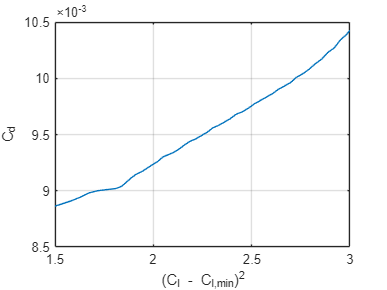

Cl_term = (Cl_data - Cl_min).^2;

figure()
plot(Cl_term,Cd_data)
xlabel('(C_l - C_l_,_m_i_n)^2')
ylabel('C_d')
xlim([1.5,3])
%ylim([0.0075,0.01])
grid on


K = (0.01039-0.00898)/(2.98287-1.67107)

K = 0.0011

## Tail Sizing

#### Specified Values

FL = 3; %fuselage length [m]
LT = 0.6*FL;
CHT = 0.55;
AR_HT = 4.5;
CVT = 0.04;
AR_VT = 1.5;

#### Calculations

S_HT = (CHT*c*S)/LT

S_HT = 0.0171

    b_HT = sqrt(AR_HT*S_HT) %wing span

b_HT = 0.2772

    c_HT = b_HT/AR_HT %chord length

c_HT = 0.0616

S_VT = (CVT*c*S)/LT

S_VT = 0.0012

    b_VT = sqrt(AR_VT*S_VT) %wing span

b_VT = 0.0432

    c_VT = b_VT/AR_VT %chord length

c_VT = 0.0288

## Control Surface Sizing

#### Specified Values

ER = 0.45; %elevator chord ratio
RR = 0.4; %rudder chord ratio

#### Calculations

c_E = c_HT*ER %elevator chord length

c_E = 0.0277

c_R = c_VT*RR %rudder chord length

c_R = 0.0115